# Lecture 4: Point Processing Operations

# Part 1: Linear operations

Author: Dr. Zeynep Cipiloglu Yildiz

Notes:

- Sample images are available in the images folder of the current directory. (You may need to add images folder into your path.)

- Related lecture: Lecture4 - Point Processing

- pdf versions of the .mlx files are also available for those using GNU Octave

% clear workspace variables and close windows
clc, clearvars, close all;

I = imread('images/blocks.tif'); %read input image file
if(size(I,3) == 3) % convert to grayscale if not
    I = rgb2gray(I);
end


## 1. Basic arithmetic operations

*Example 1: I = I+128*

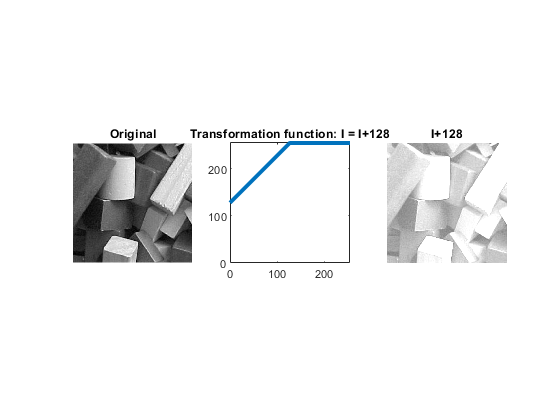

% generate transformation function
x = 0:255;
y = x+128;
ind = find(y>255);
y(ind) = 255;

% apply transformation
I1 = imadd(I,128); %add 128 to each pixel 

figure, subplot(1,3,1), imshow(I), title('Original');
subplot(1,3,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), 
title('Transformation function: I = I+128'), axis square;
subplot(1,3,3), imshow(I1), title('I+128'); %display

*Example 2: I = I - 128*

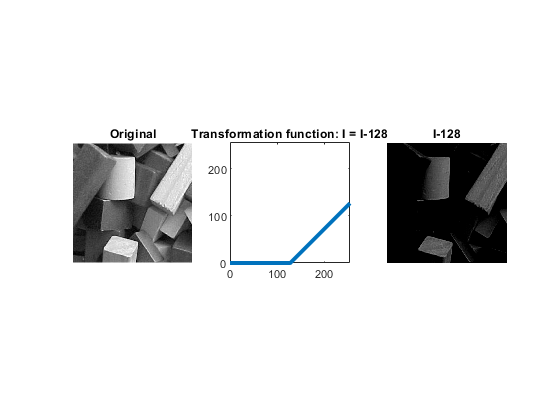

% generate transformation function
x = 0:255;
y = x-128;
ind = find(y<0);
y(ind) = 0;

% apply transformation
I2 = imsubtract(I,128); %subtract 128 from each pixel

figure, subplot(1,3,1), imshow(I), title('Original');
subplot(1,3,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), 
title('Transformation function: I = I-128'), axis square;
subplot(1,3,3), imshow(I2), title('I-128'); %display

*Example 3: I = I/2*

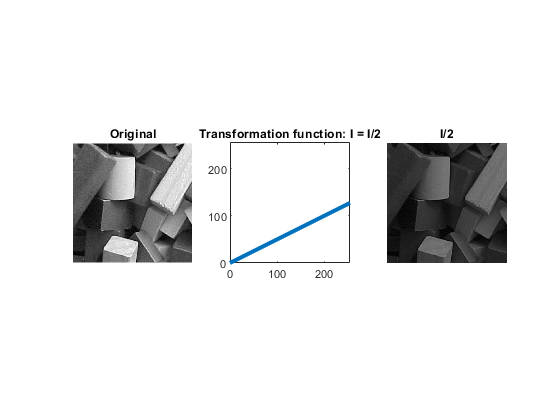

% generate transformation function
x = 0:255;
y = x/2;

% apply transformation
I3 = imdivide(I,2); %divide each pixel by 2

figure, subplot(1,3,1), imshow(I), title('Original');
subplot(1,3,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), 
title('Transformation function: I = I/2'), axis square;
subplot(1,3,3), imshow(I3), title('I/2'); %display

*Example 4: I = I*2*

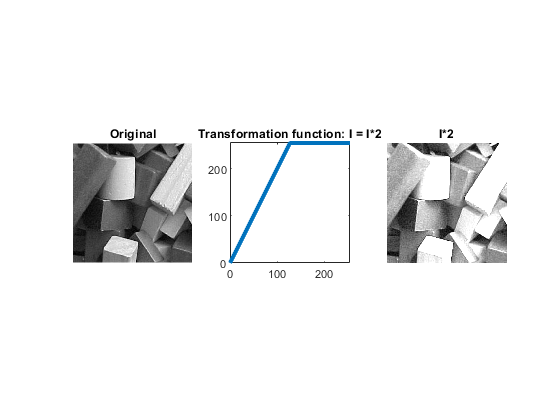

% generate transformation function
x = 0:255;
y = x*2;
ind = find(y>255);
y(ind) = 255;

% apply transformation
I4 = immultiply(I,2); %multiply each pixel by 2

figure, subplot(1,3,1), imshow(I), title('Original');
subplot(1,3,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), 
title('Transformation function: I = I*2'), axis square;
subplot(1,3,3), imshow(I4), title('I*2'); %display

*Example 5: I = I/2 + 128*

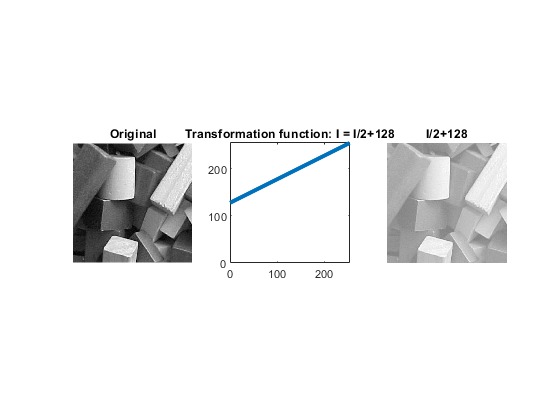

% generate transformation function
x = 0:255;
y = x/2+128;

% apply transformation
I5 = imadd(I3,128); %divide each pixel by 2, then add 128

figure, subplot(1,3,1), imshow(I), title('Original');
subplot(1,3,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), 
title('Transformation function: I = I/2+128'), axis square;
subplot(1,3,3), imshow(I5), title('I/2+128'); %display

## 2. Negative image

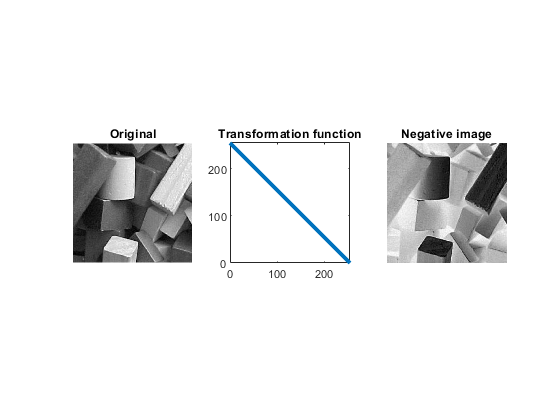

% generate transformation function
x = 0:255;
y = 255-x;

% apply transformation
I6 = imcomplement(I); %take the negative of the image

figure, subplot(1,3,1), imshow(I), title('Original');
subplot(1,3,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), 
title('Transformation function'), axis square;
subplot(1,3,3), imshow(I6), title('Negative image'); %display

## 3. Solarization

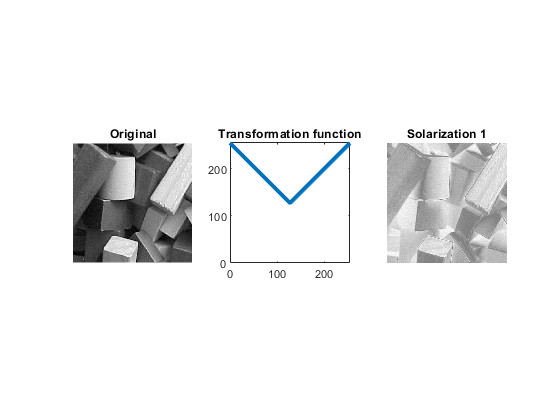

% generate transformation function
x = 0:255;
y = x;
y(1:129) = 255-y(1:129); 

% apply transformation
I7 = I; %initialize the output image with the input image
ind = find(I<=128); %find the indices of the pixels where input intensity is dark
I7(ind) = imcomplement(I(ind)); %take the negative in dark pixels

figure, subplot(1,3,1), imshow(I), title('Original');
subplot(1,3,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), 
title('Transformation function'), axis square;
subplot(1,3,3), imshow(I7), title('Solarization 1'); %display

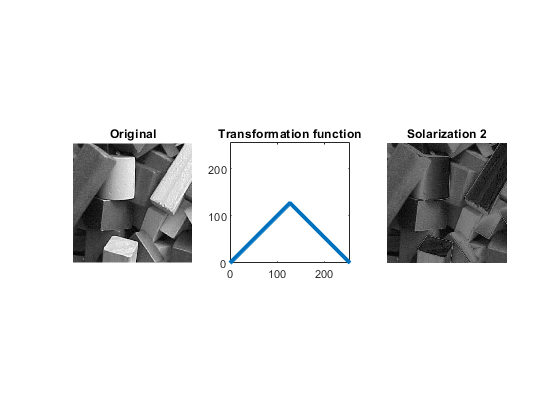

% generate transformation function
x = 0:255;
y = x;
y(130:256) = 255-y(130:256); 

% apply transformation
I8 = I; %initialize the output image with the input image
ind = find(I>128); %find the indices of the pixels where input intensity is high
I8(ind) = imcomplement(I(ind)); %take the negative in light pixels

figure, subplot(1,3,1), imshow(I), title('Original');
subplot(1,3,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), 
title('Transformation function'), axis square;
subplot(1,3,3), imshow(I8), title('Solarization 2'); %display

## 4. Thresholding

I9 = zeros(size(I)); %initialize the output image with the same size of input
th = mean(I(:)); %determine a threshold value (usually mean)
th = uint8(th)

th = uint8
109

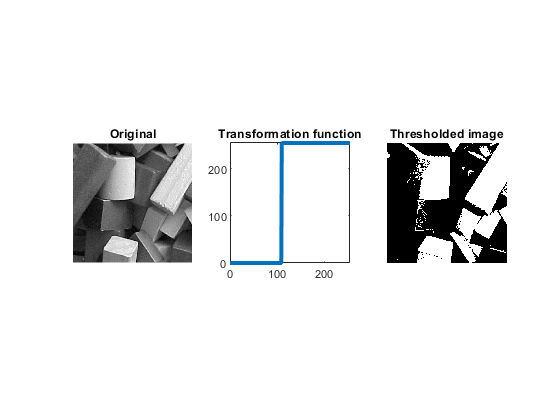

% generate transformation function
x = 0:255;
y = zeros(1,256);
ind = find(x>th);
y(ind) = 255;

% apply transformation
ind = find(I>th); %find the indices of the pixels where input intensity is above th
I9(ind) = 1; %set the pixel values to 1 if it is above th

figure, subplot(1,3,1), imshow(I), title('Original');
subplot(1,3,2), plot(x,y,'LineWidth', 3), axis([0 255 0 255]), 
title('Transformation function'), axis square;
subplot(1,3,3), imshow(I9), title('Thresholded image'); %display